# Kondensator

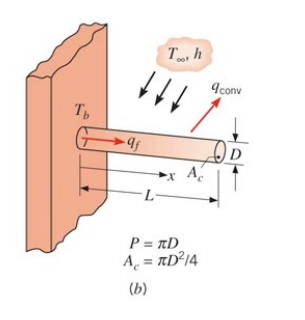

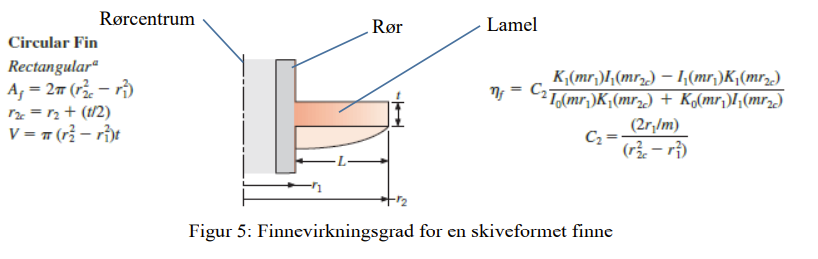

clc; clear;

%---------------------------------%
%--------- Formelsamling ---------%
%---------------------------------%

syms alpha alpha_f A T_b T_inf

% Varmestrøm fra overflade til fluid
% T_b er vægtemp, T_inf er fluidtemp (rumtemp)

Phi_f = alpha*A*(T_b - T_inf)

$$Phi\_f = A\,\alpha \,\left(T_{b}-T_{\inf}\right)$$

Phi_max = alpha_f*A*(T_b - T_inf)

$$Phi\_max = A\,\alpha_{f}\,\left(T_{b}-T_{\inf}\right)$$


eta_finne = Phi_f/Phi_max

$$eta\_finne = \frac{\alpha }{\alpha_{f}}$$


% uniforme finner eta_finne igen
syms m L_c t lambda_finne

m = sqrt(2*alpha_f/(lambda_finne*t))

$$m = \sqrt{2}\,\sqrt{\frac{\alpha_{f}}{\lambda_{\mathrm{finne}}\,t}}$$

eta_finne2 = tanh(m*L_c)/(m*L_c)

$$eta\_finne2 = \frac{\sqrt{2}\,\tanh\left(\sqrt{2}\,L_{c}\,\sqrt{\frac{\alpha_{f}}{\lambda_{\mathrm{finne}}\,t}}\right)}{2\,L_{c}\,\sqrt{\frac{\alpha_{f}}{\lambda_{\mathrm{finne}}\,t}}}$$


% Rør mellem lameller
syms D
P = pi*D

$$P = \pi \,\text{D}$$

A_c = pi*D^2/4

$$A\_c = \frac{\pi \,{\text{D}}^{2}}{4}$$



% Noget med arealer
syms H B N r_2eff

A_lam = 2*(H*B - N*pi/4 * D^2)

$$A\_lam = 2\,B\,H-\frac{\pi \,{\text{D}}^{2}\,N}{2}$$


A_lam2 = 2*N*pi*(r_2eff^2 - (D/2)^2)

$$A\_lam2 = -2\,\pi \,N\,\left(\frac{{\text{D}}^{2}}{4}-{r_{\mathrm{2eff}}}^{2}\right)$$


r_2eff_num = A_lam2 == A_lam;

r_2eff_num = solve(r_2eff_num, r_2eff)

$$r\_2eff\_num = \left(\begin{array}{c} \frac{\sqrt{B\,H\,N}}{N\,\sqrt{\pi }}\\ -\frac{\sqrt{B\,H\,N}}{N\,\sqrt{\pi }} \end{array}\right)$$



% Lamel virkningsgrad
syms r_2
r_1 = D/2

$$r\_1 = \frac{\text{D}}{2}$$

r_2 = r_2eff_num(1)

$$r\_2 = \frac{\sqrt{B\,H\,N}}{N\,\sqrt{\pi }}$$

C_2 = (2*r_1/m)/(r_2^2 - r_1^2)

$$C\_2 = -\frac{\sqrt{2}\,\text{D}}{2\,\left(\frac{{\text{D}}^{2}}{4}-\frac{B\,H}{N\,\pi }\right)\,\sqrt{\frac{\alpha_{f}}{\lambda_{\mathrm{finne}}\,t}}}$$

eta_f = C_2*(besselk(m*r_1, 1)*besseli(m*r_2, 1) - besseli(m*r_1,1)*besselk(m*r_2, 1))/(besseli(m*r_1, 0)*besselk(m*r_2, 1) + besselk(m*r_1, 0)*besseli(m*r_2, 1));


% Overordnet lamelvirkningsgrad
syms N_lam L_ror_luft H_ror
A_b = L_ror_luft * H_ror

$$A\_b = H_{\mathrm{ror}}\,L_{\mathrm{ror},\mathrm{luft}}$$

A_t = N_lam*A_lam + A_b

$$A\_t = N_{\mathrm{lam}}\,\left(2\,B\,H-\frac{\pi \,{\text{D}}^{2}\,N}{2}\right)+H_{\mathrm{ror}}\,L_{\mathrm{ror},\mathrm{luft}}$$

eta_lamel_total = 1 - (N_lam*A_lam/A_t)*(1 - eta_f);


% Luftstrømshastighed
syms rho_luft A_1 A_2 V_1 V_2

eq1 = rho_luft * A_1 * V_1

$$eq1 = A_{1}\,V_{1}\,\rho_{\mathrm{luft}}$$

eq2 = rho_luft * A_2 * V_2

$$eq2 = A_{2}\,V_{2}\,\rho_{\mathrm{luft}}$$


eq_c = eq1 == eq2;

c = solve(eq_c, V_2)

$$c = \frac{A_{1}\,V_{1}}{A_{2}}$$



% Varmeovergangstal for luftsiden
syms lambda_luft alpha_f nu_luft C


Nu = alpha_f*D/lambda_luft

$$Nu = \frac{\text{D}\,\alpha_{f}}{\lambda_{\mathrm{luft}}}$$

C = 0.38 % 5 stk forsatte

C = 0.3800



Re = c*D/nu_luft

$$Re = \frac{A_{1}\,\text{D}\,V_{1}}{A_{2}\,\nu_{\mathrm{luft}}}$$


Nu2 = C*Re^(0.6)*(A_lam/A_b)^0.15

$$Nu2 = \frac{19\,{\left(\frac{2\,B\,H-\frac{\pi \,{\text{D}}^{2}\,N}{2}}{H_{\mathrm{ror}}\,L_{\mathrm{ror},\mathrm{luft}}}\right)}^{3/20}\,{\left(\frac{A_{1}\,\text{D}\,V_{1}}{A_{2}\,\nu_{\mathrm{luft}}}\right)}^{3/5}}{50}$$


alpha_f_eq = Nu == Nu2;

alpha_f_num = solve(alpha_f_eq, alpha_f)

$$alpha\_f\_num = \frac{19\,\lambda_{\mathrm{luft}}\,{\left(\frac{2\,B\,H-\frac{\pi \,{\text{D}}^{2}\,N}{2}}{H_{\mathrm{ror}}\,L_{\mathrm{ror},\mathrm{luft}}}\right)}^{3/20}\,{\left(\frac{A_{1}\,\text{D}\,V_{1}}{A_{2}\,\nu_{\mathrm{luft}}}\right)}^{3/5}}{50\,\text{D}}$$


% Modstande
% Indvendig varmeovregangsmodstand
syms alpha_i A_i
R_i = 1/(alpha_i * A_i)

$$R\_i = \frac{1}{A_{i}\,\alpha_{i}}$$


% Varmeledningsmodstand i rørene
syms D_u D_i lambda_alu L
R_b = log(D_u/D_i)/(2*pi*L*lambda_alu)

$$R\_b = \frac{\log\left(\frac{D_{u}}{D_{i}}\right)}{2\,L\,\lambda_{\mathrm{alu}}\,\pi }$$


% Modstand for lamellerne og hele luftsiden
syms eta_0
R_f = 1/(alpha_f * A * eta_0)

$$R\_f = \frac{1}{A\,\alpha_{f}\,\eta_{0}}$$


% Vekslerens varmeydelse

syms Delta t_fi t_fu t_vi t_vu

T_LM = (t_fi - t_vu)-(t_fu - t_vi)/log((t_fi - t_vu)/(t_fu - t_vi))

$$T\_LM = t_{\mathrm{fi}}-t_{\mathrm{vu}}-\frac{t_{\mathrm{fu}}-t_{\mathrm{vi}}}{\log\left(\frac{t_{\mathrm{fi}}-t_{\mathrm{vu}}}{t_{\mathrm{fu}}-t_{\mathrm{vi}}}\right)}$$

R_tot = R_i + R_b + R_f

$$R\_tot = \frac{1}{A_{i}\,\alpha_{i}}+\frac{1}{A\,\alpha_{f}\,\eta_{0}}+\frac{\log\left(\frac{D_{u}}{D_{i}}\right)}{2\,L\,\lambda_{\mathrm{alu}}\,\pi }$$


Phi_veksler = T_LM/R_tot

$$Phi\_veksler = -\frac{t_{\mathrm{vu}}-t_{\mathrm{fi}}+\frac{t_{\mathrm{fu}}-t_{\mathrm{vi}}}{\log\left(\frac{t_{\mathrm{fi}}-t_{\mathrm{vu}}}{t_{\mathrm{fu}}-t_{\mathrm{vi}}}\right)}}{\frac{1}{A_{i}\,\alpha_{i}}+\frac{1}{A\,\alpha_{f}\,\eta_{0}}+\frac{\log\left(\frac{D_{u}}{D_{i}}\right)}{2\,L\,\lambda_{\mathrm{alu}}\,\pi }}$$